# AutoDRIVE Ecosystem | Nigel - Tire Stiffness Identification

## Clear the workspace

close all;
clear;
clc;

## Load data from .mat files

% Load the .mat files into workspace
load('skidpad_lht_0_1.mat')
load('skidpad_lht_0_2.mat')
load('skidpad_rht_0_1.mat')
load('skidpad_rht_0_2.mat')
load('straight.mat')

% Concatenate data from all the .mat files
delta = [delta_rht_0_2, delta_rht_0_1, delta_straight, delta_lht_0_1, delta_lht_0_2];
tau = [tau_rht_0_2, tau_rht_0_1, tau_straight, tau_lht_0_1, tau_lht_0_2];
v = [v_rht_0_2, v_rht_0_1, v_straight, v_lht_0_1, v_lht_0_2];
v_x = [v_x_rht_0_2, v_x_rht_0_1, v_x_straight, v_x_lht_0_1, v_x_lht_0_2];
v_y = [v_y_rht_0_2, v_y_rht_0_1, v_y_straight, v_y_lht_0_1, v_y_lht_0_2];
psi = [psi_rht_0_2, psi_rht_0_1, psi_straight, psi_lht_0_1, psi_lht_0_2];
psi_dot = [psi_dot_rht_0_2, psi_dot_rht_0_1, psi_dot_straight, psi_dot_lht_0_1, psi_dot_lht_0_2];

## **Tire slip angle estimation**

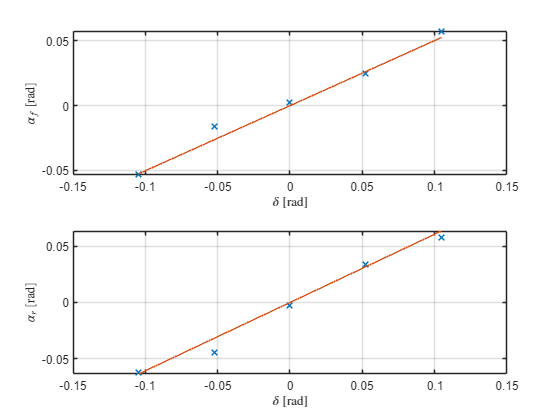

l = 0.14155; % Wheelbase (m)
l_f = 0.45*l; % Distance from CG to front axle (m)
l_r = l-l_f; % Distance from CG to rear axle (m)

beta = v_y./v_x - psi; % Estimate vehicle sideslip angle

alpha_f = - beta - (l_f.*psi_dot./v_x) + delta;
alpha_r = - beta + (l_r.*psi_dot./v_x);

delta_alpha_f = polyfix(delta, alpha_f, 1, 0, 0);
delta_alpha_r = polyfix(delta, alpha_r, 1, 0, 0);

figure()
subplot(2,1,1);
plot(delta,alpha_f,'x',LineWidth=1);
hold on
plot(delta,polyval(delta_alpha_f,delta));
xlabel('$\delta$ [rad]', 'Interpreter', 'latex')
ylabel('$\alpha_f$ [rad]', 'Interpreter', 'latex')
grid on
subplot(2,1,2);
plot(delta,alpha_r,'x',LineWidth=1);
hold on
plot(delta,polyval(delta_alpha_r,delta));
xlabel('$\delta$ [rad]', 'Interpreter', 'latex')
ylabel('$\alpha_r$ [rad]', 'Interpreter', 'latex')
grid on

## **Tire stiffness estimation**

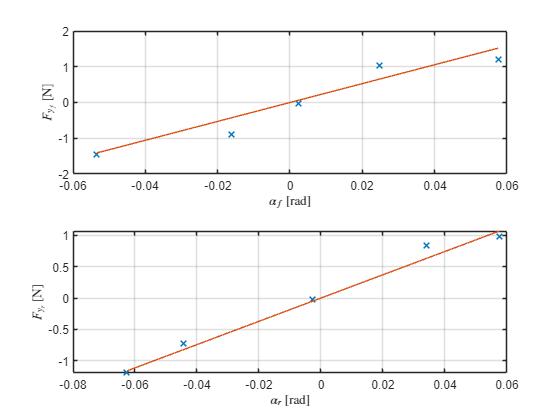

m = 2.68; % Mass (kg)
a_y = 9.9365.*v_x.*psi_dot; % Lateral acceleration (m/s^2)

Fy_f = (m.*a_y.*l_r)./l; % Front tire force
Fy_r = (m.*a_y.*l_f)./l; % Rear tire force

force_alpha_f = polyfix(alpha_f, Fy_f, 1, 0, 0);
force_alpha_r = polyfix(alpha_r, Fy_r, 1, 0, 0);

figure()
subplot(2,1,1);
plot(alpha_f,Fy_f,'x',LineWidth=1);
hold on
plot(alpha_f,polyval(force_alpha_f,alpha_f));
xlabel('$\alpha_f$ [rad]', 'Interpreter', 'latex')
ylabel('$F_{y_f}$ [N]', 'Interpreter', 'latex')
grid on
subplot(2,1,2);
plot(alpha_r,Fy_r,'x',LineWidth=1);
hold on
plot(alpha_r,polyval(force_alpha_r,alpha_r));
xlabel('$\alpha_r$ [rad]', 'Interpreter', 'latex')
ylabel('$F_{y_r}$ [N]', 'Interpreter', 'latex')
grid on

result = sprintf('Tire Stiffness: %.4f N/rad', (force_alpha_f(1)+force_alpha_r(1))/2);
disp(result);

Tire Stiffness: 22.4768 N/rad
